# Sample 11-2

## 画像ノイズ除去

ノイズの変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Transform of noise

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

- nlevels: ウェーブレット段数 (Wavelet levels)

% Parameter settings
sgmuint8 = 30; 
sgm = sgmuint8/255;
nlevels = 3; 

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/kodim23.png')));

## 分析処理

(Analysis process)

直交ウェーブレット変換Symlet を利用．(Uses Symlet, which is an orthogonal wavelet transform.)

% Preperation of filters for wavelets
iswtb = license('checkout','wavelet_toolbox');
if iswtb % Functions in Wavelet Toolbox are used
    dwtmode('per')
    wname = "sym4";
    [h0,h1,f0,f1] = wfilters(wname);
    %save(['./data/' char(wname) '.mat'],'h0','h1','f0','f1')
else
    import msip.ezwavedec2
    import msip.ezwaverec2
    S = load('./data/sym4.mat');
    h0 = S.h0;
    h1 = S.h1;
    f0 = S.f0;
    f1 = S.f1;
    clear H  F
    % Analysis bivariate filters
    H.h00 = h0(:)*h0(:).';
    H.h01 = h0(:)*h1(:).';
    H.h10 = h1(:)*h0(:).';
    H.h11 = h1(:)*h1(:).';
    % Synthesis bivariate filters
    F.f00 = f0(:)*f0(:).';
    F.f01 = f0(:)*f1(:).';
    F.f10 = f1(:)*f0(:).';
    F.f11 = f1(:)*f1(:).';
end

 
!!!!!!!!!!!!!!!!!!!!!!!!!
!  警告:DWT 拡張モードを変更してください。
!!!!!!!!!!!!!!!!!!!!!!!!!
                      
**********************
**  DWT 拡張モード: 周期化  **
**********************
                      


分析処理 (Analysis process)

if iswtb
    [coefs,scales] = wavedec2(u,nlevels,h0,h1);
    % Reconstruction to check PR
    r = waverec2(coefs,scales,f0,f1);
else
    [coefs,scales] = ezwavedec2(u,nlevels,H);
    % Reconstruction to check PR%
    r = ezwaverec2(coefs,scales,F);
end
assert(norm(u-r,"fro")^2/numel(u)<1e-18,'Perfect reconstruction is violated.')

変換係数の配列化 (Alighment of coefficients)

uc = aligncoefs(coefs,scales);

## 観測画像

(Observation image)

v = imnoise(u,'gaussian',0,sgm^2);

分析処理 (Analysis process)

if iswtb
    [coefs,scales] = wavedec2(v,nlevels,h0,h1);
else
    [coefs,scales] = ezwavedec2(v,nlevels,H);
end

%% 変換係数の配列化
pos = 0;
dim = scales(1,:);

変換係数の配列化 (Alighment of coefficients)

vc = aligncoefs(coefs,scales);

### 画像表示

(Image show)

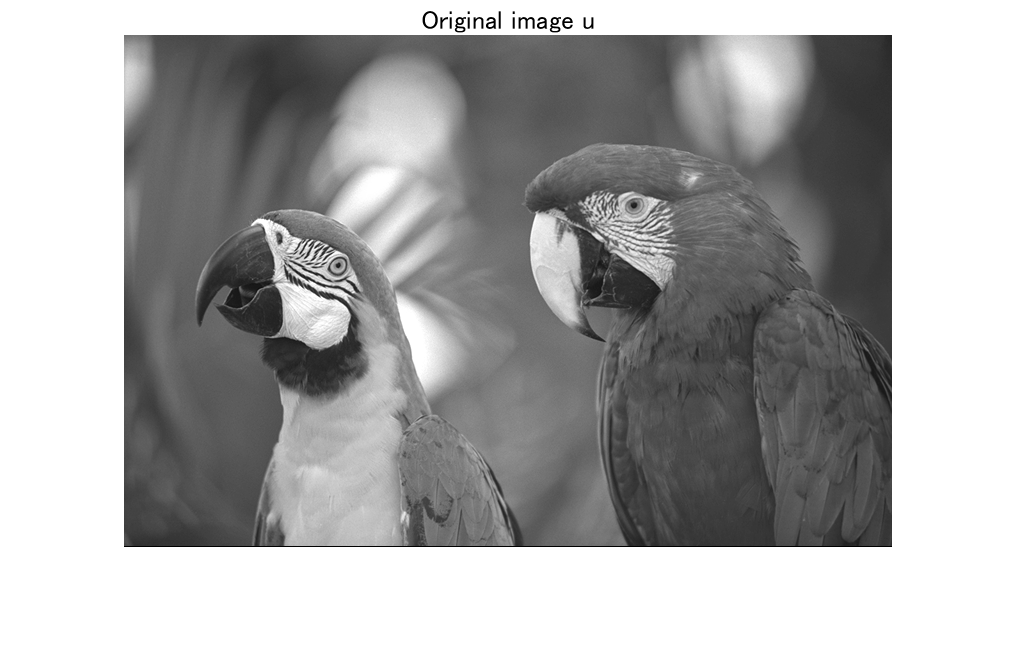

figure(1)
imshow(u);
title('Original image u')

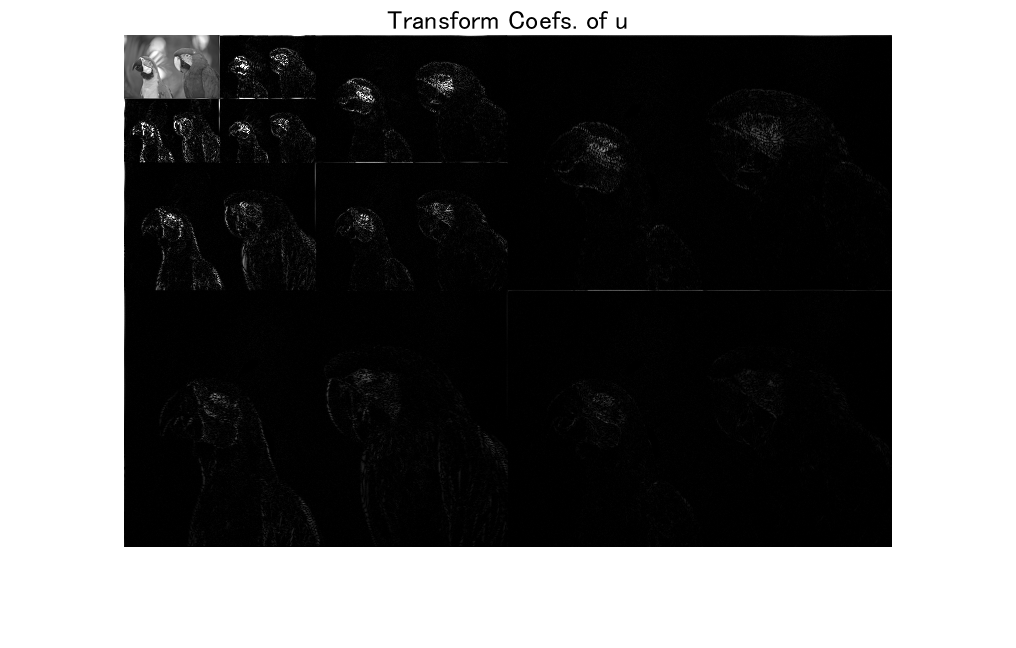

figure(2)
imshow(abs(uc))
title('Transform Coefs. of u')

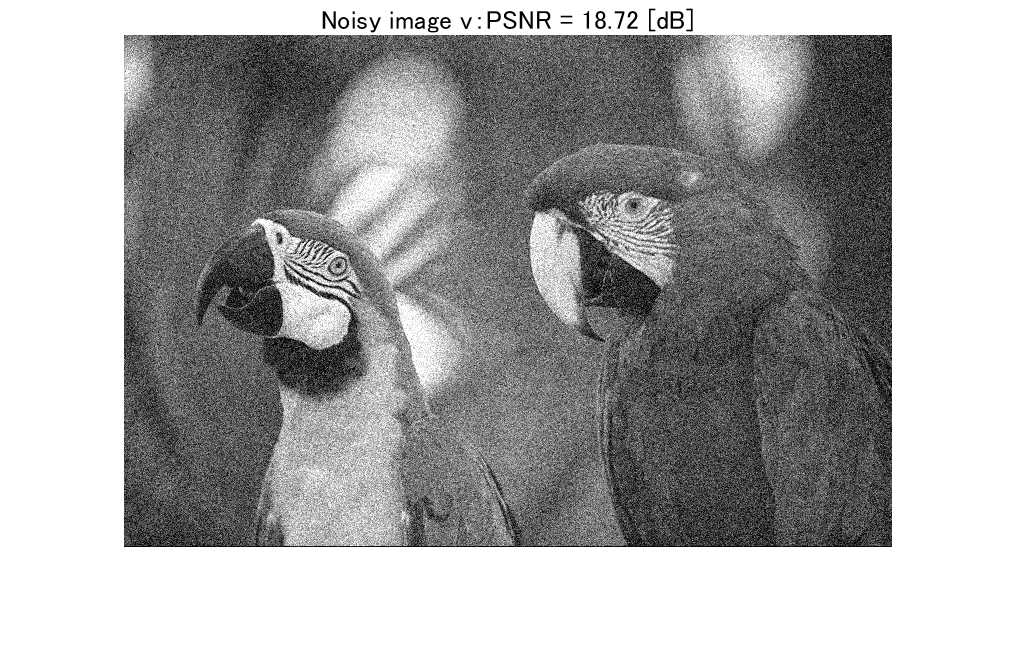

figure(3) 
imshow(v)
title(sprintf('Noisy image v：PSNR = %5.2f [dB]',psnr(u,v)))

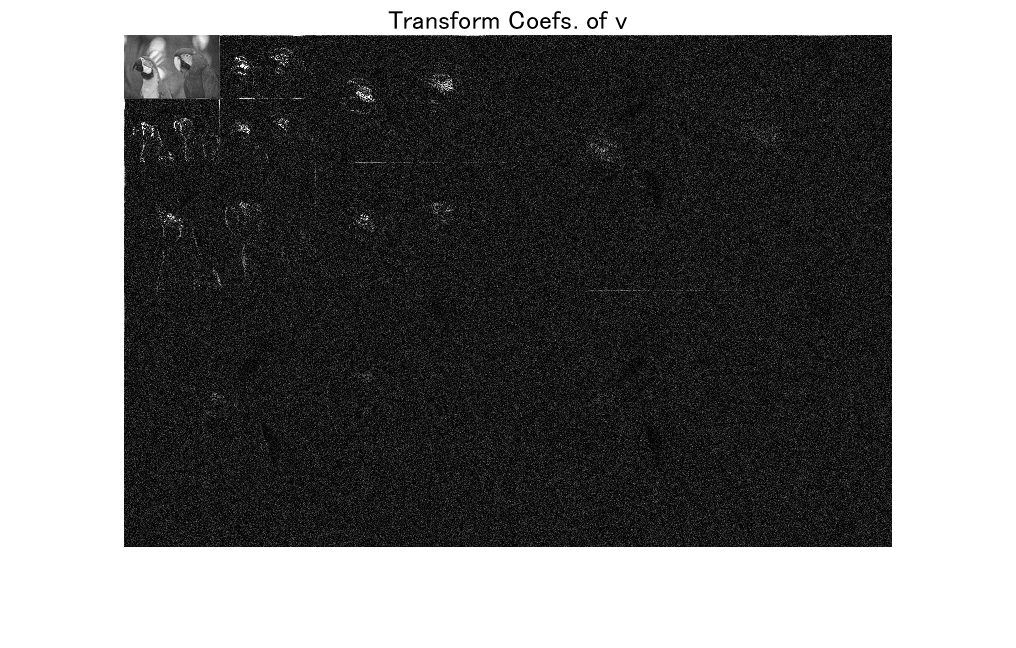

figure(4)
imshow(abs(vc))
title('Transform Coefs. of v')

### 関数定義

(Definition of function)

変換係数の配列化 (Alighment of coefficients)

function c00 = aligncoefs(coefs,scales)
nlevels = size(scales,1)-2;
pos = 0;
dim = scales(1,:);
nel = prod(dim);
c00 = reshape(coefs(pos+1:pos+nel),dim)/(2^nlevels);
pos = nel;
for ilv = 1:nlevels
    dim = scales(ilv+1,:);
    nel = prod(dim);
    %
    c01 = abs(reshape(coefs(pos+1:pos+nel),dim));
    pos = pos + nel;
    %
    c10 = abs(reshape(coefs(pos+1:pos+nel),dim));
    pos = pos + nel;
    %
    c11 = abs(reshape(coefs(pos+1:pos+nel),dim));
    pos = pos + nel;
    %
    c00 = [ c00 c01; c10 c11 ];
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.